**INITIAL CLEARANCE OF THE WORKSPACE**

clear all;

**FILE IMPORT AND UNPACK**

% load camera parameters
load('../../Camera_Kalibrierung\Cam_Param_1.mat');



% define the physical dimensions of a checkerboard square in millimeters.
squareSize = 30;
imageDimensions = cameraParams.ImageSize;
cameraIntrinsics = cameraParams.Intrinsics;

% read the image of the checkerboard
image = imread('.\Images\04_lab_checkerboard_Color.png');

transformationMatrix = PCSToRCSTransform(image, squareSize, cameraParams);

score = 100.6166

lenTranslation = 778.2632

controlPoint = 1×4 single row vector
   -0.0000   -0.0000         0    1.0000


pp = 4×1 single column vector
  676.3351
  385.0512
         0
    1.0000


tpp = 4×1 single column vector
  716.4828
  355.2491
         0
    1.0000


**CALCULATE THE CHECKERBOARD POSITION**

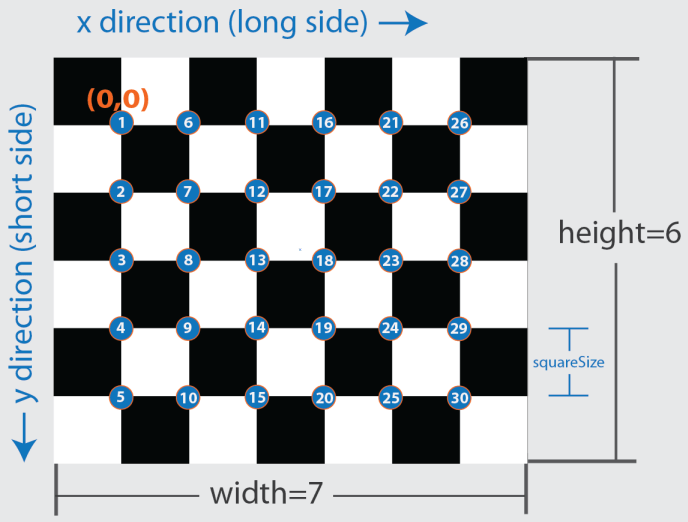

function finalTransformation = PCSToRCSTransform(image, squareSize, camParameters)

% identify the points of intersection in the checkerboard pattern and
% return them as a list of xy coordinates.
% https://de.mathworks.com/help/vision/ref/detectcheckerboardpoints.html#responsive_offcanvas
[checkerboardPointsPCS, checkerboardSize] = detectCheckerboardPoints(image);

% unpack principal point and intrinsic camera matrix
principalPointPCS = int64(camParameters.PrincipalPoint);
cameraIntrinsics = camParameters.Intrinsics;

% generate the coordinates of the points of intersection within the
% checkerboard pattern. The unit is determined by the unit chosen in
% squareSize.
% https://de.mathworks.com/help/vision/ref/generatecheckerboardpoints.html#responsive_offcanvas
checkerboardPointsBCS = generateCheckerboardPoints(checkerboardSize, squareSize);


% get the world coordinates xy of the checkerboard points of intersection
checkerboardPointsCCS = constructCheckerboardInCCS(checkerboardPointsPCS, checkerboardPointsBCS, ...
    checkerboardSize, principalPointPCS);

% estimate an extrinsic transformation matrix
% https://de.mathworks.com/help/vision/ref/estimateextrinsics.html#responsive_offcanvas
cameraExtrinsics = estimateExtrinsics(checkerboardPointsPCS, checkerboardPointsCCS, cameraIntrinsics);

% check the transformed checkerboard diagonal against an ideal diagonal calculated from the checkerboard metadata
score = checkPlausability(checkerboardPointsPCS, cameraExtrinsics, cameraIntrinsics, checkerboardSize, squareSize)

% calculate a new set of checkerboard points in ccs
checkerboardPointsCCS = img2world2d(checkerboardPointsPCS, cameraExtrinsics, cameraIntrinsics);

% construct the 42 checkerboard points from points 1 and 6 in the rcs
boardOriginRCS = [357.2  65.4]; % point 1 in rcs
boardCornerRCS = [353.4 -85.62]; % point 6 in rcs
checkerboardPointsRCS = constructCheckerboardInRCS(boardOriginRCS, boardCornerRCS, checkerboardSize, squareSize);

% match orientation of ccs and rcs
transformationMatrix = matchOrientation(checkerboardPointsCCS, checkerboardPointsRCS);

finalTransformation = rigidtform3d(transformationMatrix);

% check transformation matrix by transforming the principal point and
% another point
controlPoint = img2world2d(principalPointPCS, cameraExtrinsics, cameraIntrinsics);
controlPoint(4) = 1

pp = finalTransformation.A * controlPoint'

controlPoint(1) = 50;

tpp = finalTransformation.A * controlPoint'
end

**VISUALIZATION**

% % Display the image and plot the detected corners and axes.
% imshow(image);
% hold on;
% 
% drawPCS(100);
% drawCCS(principalPointPCS, 100);
% drawImagePoints(checkerboardPointsPCS);
% drawBCS(checkerboardPointsPCS, checkerboardSize);
% 
% % highlight the origin and point 6 with green circles.
% highlightPoint(checkerboardPointsPCS, 1)
% highlightPoint(checkerboardPointsPCS, 6)
% 
% % measure the real world distances along the x and y axis of the ccs and
% % visualize them
% measurePointAndPlot(checkerboardPointsPCS, 1, principalPointPCS, cameraExtrinsics, cameraIntrinsics, 4);
% measurePointAndPlot(checkerboardPointsPCS, 6, principalPointPCS, cameraExtrinsics, cameraIntrinsics, -4);
% 
% hold off;

**CHECKERBOARD POINTS OF INTERSECTION IN CCS**

function checkerboardPointsCCS = constructCheckerboardInCCS(checkerboardPointsPCS, checkerboardPointsBCS, checkerboardSize, principalPointPCS)

dimensionX = checkerboardSize(2) - 1;
dimensionY = checkerboardSize(1) - 1;

% get the real square edge length from an arbitrary adjacent pair of checkerboard pattern points
squareSizeReal = norm(checkerboardPointsBCS(1,:) - checkerboardPointsBCS(2,:));

% calculate the list length
n = dimensionX * dimensionY;

% initialize lists of length n 
pixelDistancesX = eye(n, 1);
pixelDistancesY = eye(n,1);

% get the image square edge lengths as mean pixel distance between the
% adjacent checkerboard image points
for i = 1:n
    if i <= (n - dimensionY)
        to = i + dimensionY;
        pixelDistancesX(i) = norm(checkerboardPointsPCS(i,:) - checkerboardPointsPCS(to,:));
    else
        pixelDistancesX(i) = NaN;
    end
    if mod(i, dimensionY) ~= 0
        pixelDistancesY(i) = norm(checkerboardPointsPCS(i,:) - checkerboardPointsPCS(i+1,:));
    else
        pixelDistancesY(i) = NaN;
    end
end

squareSizeImage = mean(cat(1, pixelDistancesX, pixelDistancesY), 'omitnan');

% calculate a scaling factor from the ratio of the square edge lengths
scalingFactor = squareSizeReal / squareSizeImage;

checkerboardPointsCCS = (double(principalPointPCS) - checkerboardPointsPCS) * scalingFactor;
end

**CHECKERBOARD POINTS OF INTERSECTION IN RCS**

function pointsRCS = constructCheckerboardInRCS(boardOriginRCS, boardCornerRCS, checkerboardSize, squareSize)
dimensionX = checkerboardSize(2) - 1;
dimensionY = checkerboardSize(1) - 1;

vectorA = boardCornerRCS - boardOriginRCS;
vectorA = vectorA / norm(vectorA);

pointsRCS = zeros(dimensionY, 2);

for i=1:dimensionY
    pointsRCS(i,:) = boardOriginRCS + (i-1) * squareSize * vectorA;
end

vectorA(3) = 0;
vectorZ = [0 0 1];
vectorB = cross(-vectorA, vectorZ);
vectorB = vectorB(1:2) * squareSize;

for j = 1: (dimensionX - 1)
    newPointsRCS = pointsRCS(1:dimensionY,:) + j * vectorB;
    pointsRCS = cat(1,pointsRCS, newPointsRCS);
end
end

**MATCH ORIENTATION OF CCS AND RCS**

function transformationMatrix = matchOrientation(checkerboardPointsCCS, checkerboardPointsRCS)

vectorCCS = checkerboardPointsCCS(1,:) - checkerboardPointsCCS(6,:);
vectorCCS = vectorCCS / norm(vectorCCS);
vectorCCS(3) = 0;

vectorRCS = checkerboardPointsRCS(1,:) - checkerboardPointsRCS(6,:);
vectorRCS = vectorRCS / norm(vectorRCS);
vectorRCS(3) = 0;

% rotate the ccs vector by 180 degree around the x axis to match
% orientation of the z axes
rotationX = rotx(pi);
vectorCCS = rotationX * vectorCCS';
% vectorCCS = vectorCCS(1, 1:2)


angleZ = acos(dot(vectorCCS, vectorRCS));
rotationZ = rotz(angleZ);

checkerboardPointsCCS(:,3) = 0;
rotationMatrix =  rotationX * rotationZ;
checkerboardPointsCCS = rotationMatrix * checkerboardPointsCCS';

checkerboardPointsCCS = checkerboardPointsCCS(:, 1:2);
translationVector = checkerboardPointsRCS(1,:) - checkerboardPointsCCS(1,:);

lenTranslation = norm(translationVector)

transformationMatrix = eye(4);
transformationMatrix(1:3, 1:3) = rotationMatrix;
transformationMatrix(1:2, 4) = translationVector;
end

**PLOT IMAGE POINTS AS CIRCLES**

function drawImagePoints(pointsPCS)

offset = 5;

% draw circles around the points of intersection
plot(pointsPCS(:, 1), pointsPCS(:, 2), 'ro');

% label these circles with their index
for i = 1:size(pointsPCS, 1)
    text(pointsPCS(i, 1) + offset, pointsPCS(i, 2), num2str(i), 'Color', 'y', 'FontSize', 8);
end
end

**PLOT CAMERA COORDINATE SYSTEM**

function drawCCS(principalPointPCS, axisLength)

offset = 5;

% construct the three points to draw a 2d coordinate frame
framePoints = [principalPointPCS; principalPointPCS; principalPointPCS];
framePoints(1,1) = framePoints(1,1) - axisLength;
framePoints(3,2) = framePoints(3,2) - axisLength;

% draw the x axis in red
line(framePoints(1:2,1), framePoints(1:2,2), 'Color', 'r', 'LineWidth', 2);
% draw the y axis in green
line(framePoints(2:3,1), framePoints(2:3,2), 'Color', 'g', 'LineWidth', 2);
% write the frame name aside the axes
text(framePoints(2,1) + offset, framePoints(2,2), 'CCS', 'Color', 'b', 'FontSize', 8);
end

**PLOT PIXEL COORDINATE SYSTEM**

function drawPCS(axisLength)

offset = 10;

framePoints = [[offset offset]; [offset offset]; [offset offset]];
framePoints(1,1) = framePoints(1,1) + axisLength;
framePoints(3,2) = framePoints(3,2) + axisLength;

% draw the x axis in red
line(framePoints(1:2,1), framePoints(1:2,2), 'Color', 'r', 'LineWidth', 2);
% draw the y axis in green
line(framePoints(2:3,1), framePoints(2:3,2), 'Color', 'g', 'LineWidth', 2);
% write the frame name aside the axes
text(framePoints(2,1) + offset + 5, framePoints(2,2) + offset + 5, 'PCS', 'Color', 'b', 'FontSize', 8);
end

**PLOT CHECKERBOARD COORDINATE SYSTEM**

function drawBCS(pointsPCS, checkerboardSize)

offset = 10;

% construct the three points to draw a 2d coordinate frame
framePoints = [pointsPCS(checkerboardSize(1),:); pointsPCS(1,:); pointsPCS(2,:)];

% draw the x axis in red
line(framePoints(1:2,1), framePoints(1:2,2), 'Color', 'r', 'LineWidth', 2);
% draw the y axis in green
line(framePoints(2:3,1), framePoints(2:3,2), 'Color', 'g', 'LineWidth', 2);
% write the frame name aside the axes
text(framePoints(2,1) + offset, framePoints(2,2), 'BCS', 'Color', 'y', 'FontSize', 8);
end

function highlightPoint(imagePoints, index)
plot(imagePoints(index, 1), imagePoints(index, 2), 'go', 'MarkerSize', 10);
end

**MEASURE POINT DISTANCE TO PRINCIPLE POINT AND PLOT**

function measurePointAndPlot(pointsPCS, index, principalPointPCS, cameraExtrinsics, cameraIntrinsics, scetchOffset)

imagePoint = pointsPCS(index,:);
principalPointPCS = double(principalPointPCS);

% transform the principal point to the ccs
principalWorldPoint = img2world2d(principalPointPCS, cameraExtrinsics, cameraIntrinsics);

% transform the chosen point to the ccs
imageWorldPoint = img2world2d(imagePoint, cameraExtrinsics, cameraIntrinsics);

% get both the pixel and real world distances between principal point and
% the selected image point
pixelDistance = imagePoint - principalPointPCS;
worldDistance = imageWorldPoint - principalWorldPoint;

% manage the offset for visualization ...
offprincipalPointPCS = principalPointPCS + scetchOffset;
xPoint = offprincipalPointPCS + [pixelDistance(1) 0];
yPoint = offprincipalPointPCS + [0 pixelDistance(2)];

% ... and merge the frame points
framePoints = [xPoint; offprincipalPointPCS; yPoint];

% plot the distances and labels in a random color
color = [rand,rand,rand];
plot(framePoints(:,1), framePoints(:,2), 'Color', color, 'LineWidth', 2);
text(framePoints(1,1), framePoints(1,2), ['P', num2str(index), 'X: ', num2str(int64(worldDistance(1))), ' mm'], 'Color', color, 'FontSize', 15);
text(framePoints(3,1), framePoints(3,2), ['P', num2str(index), 'Y: ', num2str(int64(worldDistance(2))), ' mm'], 'Color', color, 'FontSize', 15);
end

**CHECK PLAUSABILITY OF CALCULATED CAMERA EXTRINSICS**

function score = checkPlausability(pointsPCS, cameraExtrinsics, cameraIntrinsics, checkerboardSize, squareSize)

dimensionX = checkerboardSize(2) - 2;
dimensionY = checkerboardSize(1) - 2;

idealDiagonal = sqrt(dimensionX^2 + dimensionY^2) * squareSize;

diagonalPoints = [pointsPCS(1,:); pointsPCS((dimensionX + 1)*(dimensionY + 1), :)];
diagonalWorldPoints = img2world2d(diagonalPoints, cameraExtrinsics, cameraIntrinsics);

approxDiagonal = norm(diagonalWorldPoints(1, :) - diagonalWorldPoints(2, :));

score = 100 * approxDiagonal / idealDiagonal;
end